## Implicit Methods

In this livescript, you will learn how

- To solve initial value problems using implicit methods.

The two implicit methods that we have covered in this course are the* implicit Euler method*


$$x_{n+1}=x_{n}+\Delta t f(t_{n+1},x_{n+1})$$


and the *Crank-Nicolson method*


$$x_{n+1}=x_{n}+\frac{\Delta t}{2}(f(t_{n},x_{n})+f(t_{n+1},x_{n+1}))$$


To look at how to apply these, consider the initial value problem 


$$\frac{dx}{dt}=-x^2$$


with the initial condition $x(0)=1$.

Before we solve this we'll again initialise out variables and define all the relevant parameters.

dt = 0.01;
t = 0:dt:20;
x = zeros(1,length(t));
x(1) = 1;

For the sake of brevity, we'll consider the implicit Euler method, which gives the iterative formula


$$x_{n+1}=x_{n}-\Delta t x_{n+1}^{2}$$


However, we can see that there is a nonlinear dependence on $x_{n+1}$. Nevertheless, we can write this as the root finding problem with $p=x_{n+1}$


$$f(p)=\Delta t p^{2}+p-x_{n}=0$$


To solve this we can apply the Newton-Raphson method to give 


$$p^{(i+1)}=p^{(i)}-\frac{f(p^{(i)})}{f'(p^{(i)})}$$


The only issue is how we choose our initial guess for the Newton-Raphson method.

Assuming that the solution is continuous, which is required for the Newton-Raphson method, then $x_{n}$ will be somewhat close to the next iterate $x_{n+1}$. So, for the first iterate, we have the piece of code

p = x(1);
i = 1;
f = dt*p^2+p-x(1);
tol=10^-6;
max_iter=100;
    
while abs(f)>tol && i<max_iter
    p = p-(dt*p^2+p-x(1))/(2*dt*p+1);
    i = i+1;
end
    
x(2) = p

x =     1.0000    0.9902         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Wrapping everythin in a for loop to march forward in time, we have

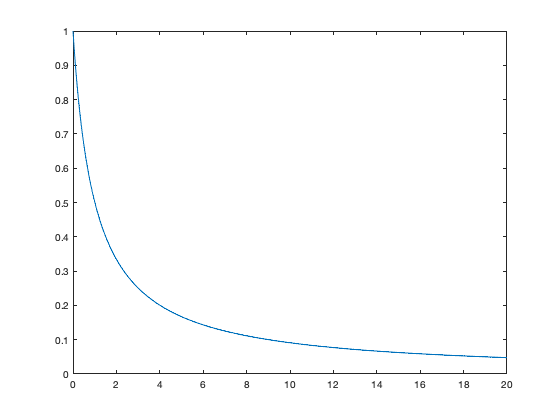

dt = 0.01;
t = 0:dt:20;
x = zeros(1,length(t));
x(1) = 1;

max_iter = 20;
tol = 1e-6;

for n = 1:length(t)-1
    
    p = x(n);
    i = 1;
    f = dt*p^2+p-x(n);
    
    while abs(f)>tol && i<max_iter
        p = p-(dt*p^2+p-x(n))/(2*dt*p+1);
        i = i+1;
    end
    
    x(n+1) = p;
    
end

plot(t,x)